# **Learning and Estimation of Dynamical Systems - Project**

## **0. Initialization**

clear all
close all
addpath ./Functions/

Student = "Alessandro Cecconi";
Matriculation = '0000983867';

# Exercise 1 - Estimation Problem

### **1) Understand The model Structure**

N = 10000; 
[Measurements] = IdentifyThis(N,Student,Matriculation);

u = Measurements.u;
y = Measurements.y;

To identify the model structure let's see the plot of input and output:

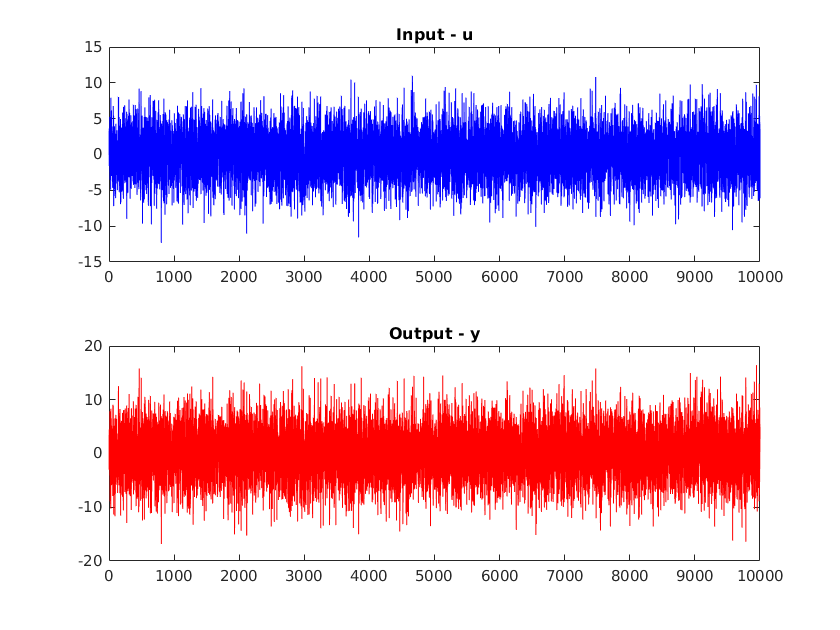

figure
hold on
subplot(2,1,1)
plot(u,'b')
title("Input - u")
subplot(2,1,2)
plot(y,'r')
title("Output - y")
hold off

From the plot we can see that the input $u(t)$ is not zero, so for sure we have to deal with an ARX model, which has the following form:


$$y(t) = -a_1y(t-1) - \dots -a_ny(t-n) + b_1u(t-1) + \dots + b_nu(t-n) + e(t)$$


From the plot the input resembles a white noise, we can try to see if it is true by looking at its autocorrelation function up to $\tau=10$:

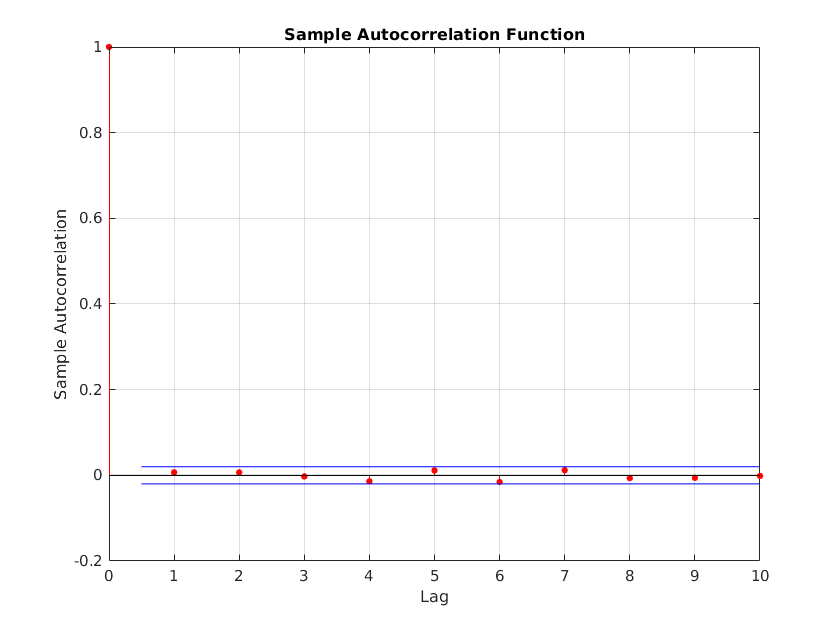

lag = 10;
figure
autocorr(u,lag)

From the figure is clearly visible that our input is a white noise, remembering that the matlab function autocorr gives back the normalized autocorrelation function, i.e. 

$r_u(\tau) = \frac{r_u(\tau)}{r_u(0)}$  for $\tau = 0,\dots,10$

We say that the input is a white noise because its autocorrelation function is 0 at every instant but not at $\tau = 0$, where it coincides with its variance $\sigma^2_u$. The autocorrelation function of a white noise can be compactly written as

$r_u(\tau) = \sigma_u^2\delta(\tau)$, where $\delta(\tau)$ is the Kroenecker Function defined as


$$\delta \left(\tau \right)=\left\lbrace \begin{array}{ll}
1 & \tau =0\\
0 & \tau \not= 0
\end{array}\right.$$


A white noise is a good input signal for an estimation problem, since is persistently excited of ANY order, which means in practice that excites all the system modes in the same way. In our case, since we are dealing with an ARX model, the hankel matrix depends from past samples of the input signals ( and of the output as well) , and the identifiability condition is fullfilled if the input is p.e. of order $\ge n$. Since our input is a white noise, the identifiablity is for sure satisfied and we will get a unique solution of our estimation problem. 

### 2) Define the required Estimation Algorithm

Our goal is to identify the parameters which represents the system behaviour (i.e. $a_1,\dots,a_n,b_1,\dots,b_n$). In order to do that we rely on the Linear Regression theory to solve the task. Since the model is linear in the parameters, the ARX model can be rewritten in the form:


$$y(t) = \varphi(t)^T\theta + \epsilon(t)$$


where:

$\varphi(t)^T = [-y(t-1)\ \dots \ -y(t-n)\ u(t-1)\ \dots \ u(t-n)]$ is the regressor vector

$\theta= [a_1\ \dots\ a_n\ b_1 \ \dots \ b_n]^T$ is the parameters vector

The model complexity is the dimension of the parameters vector, i.e. $2n$. 

The problem can be written in condensed form by defining the Hankel Matrix $H(n)$ as:


$$H(n) = [ -H_y(n) \ H_u(n)] = $$

$$\left\lbrack \begin{array}{cccccc}
-y\left(0\right) & \ldotp \ldotp \ldotp  & -y\left(1-n\right) & u\left(0\right) & \ldotp \ldotp \ldotp  & u\left(1-n\right)\\
-y\left(1\right) & \ldotp \ldotp \ldotp  & -y\left(2-n\right) & u\left(1\right) & \ldotp \ldotp \ldotp  & u\left(2-n\right)\\
\vdots  & \ddots  & \vdots  & \vdots  & \ddots  & \vdots \\
-y\left(N\right) & \ldotp \ldotp \ldotp  & -y\left(N-n\right) & u\left(N\right) & \cdots  & u\left(N-n\right)
\end{array}\right\rbrack$$


which is the matrix that contains all the previous samples of outputs and inputs at the different time instant, and from its block structure it is easy to see that it is full rank (= 2n) if both its sub-matrices $H_u(n)$ and $H_y(n)$ are full rank (i.e. both of them must have rank = n).

So the problem can be written in compact form as:

 
$$Y = H(n)\theta + \epsilon$$


The least square method tells us that once an estimate is available, we can compute the residuals which are the misfit between the real values and the estimated ones, i.e. $\epsilon(t) = y(t) - \hat{y}(t)$. The LS method finds a parameters vector $\hat{\theta}$ such that the following cost function is minimized:


$$J(\theta) = \frac{1}{N}\sum_{t=1}^N\epsilon^2(t) = \frac{1}{N}\epsilon^T\epsilon=\frac{1}{N}(Y-H\theta)^T(Y-H\theta)$$


By some calculus, the value the solution that minimizes the cost function is:


$$\hat{\theta}_N = \bigg(\frac{H^TH}{N}\bigg)^{-1}\frac{H^TY}{N}$$


The following solution comes from the "batch" case, where we have all the samples needed to compute the estimate. However, To solve the estimation problem ask to apply the Recursive Least Square Algorithm with forgetting factor (or RWLS), which can be applied also in the case we do not have the entire dataset stored, but we refine our estimate when new data come. And in particular, the version with the forgetting actor is able to track also parameters variation in the plant/system by giving less importance to past data using the forgetting factor $\lambda$. The cost function is rewritten as:

$J(\theta) = \sum_{t=1}^N\lambda^{N-t}\epsilon^2(t) = \epsilon^TW\epsilon$ with $0\le\lambda\leq1$

where:


$$W = diag(\lambda^{N-1}\ \dots \ \lambda\ 1)$$


Usually $\lambda\in[0.95\ \dots \ 1]$ otherwise it will decade so fastly that only few samples are used. 

To apply the RWLS we should know which is the model order, otherwise we cannot start the algorithm. Because of that, we will first estimate which is the model order.

I will implement two different RWLS, the RWLS I and RWLS III. They are pretty much similar, but in III we will avoid the matrix inversion at each iteration by means of the Matrix Inversion Lemma.

I am going to start from:


$$$\hat{\theta}(t) = \bigg(\sum_{k=1}^t\lambda^{t-k}\varphi(k)\varphi^T(k)\bigg)^{-1}\varphi(t)y(t)$$


That can be seen as a partial sum of up to the data we have at time t weighted with forgetting factor $\lambda$, and it is in fact the starting point for the recursive form. Defining the quantity $S(t) = \sum_{k=1}^t\lambda^{t-k}\varphi(k)\varphi^T(k)$ the two algorithms can be summarized as follows:

**RWLS I**

- 
$$S(t)^{-1} = \lambda S(t-1) + \varphi(t)y(t)$$


- 
$$K(t) = S(t)^{-1}\varphi(t)$$


- 
$$\epsilon(t) = y(t) - \varphi^T(t)\hat{\theta}(t-1)$$


- 
$$\hat{\theta} = \hat{\theta}(t-1) + K(t)\epsilon(t)$$


**RWLS III**

- 
$$S(t)^{-1} = \frac{S(t-1)^{-1}}{\lambda} - \frac{S(t-1)^{-1}\varphi(t)\varphi^T(t)S(t-1)^{-1}}{\lambda(\lambda + \varphi^T(t)S(t-1)^{-1}\varphi(t))}$$


- 
$$K(t) = S(t)^{-1}\varphi(t)$$


- 
$$\epsilon(t) = y(t) - \varphi^T(t)\hat{\theta}(t-1)$$


- 
$$\hat{\theta} = \hat{\theta}(t-1) + K(t)\epsilon(t)$$


We can define a simple change of variable $P(t) = S(t)^{-1}$, And then rewrite the RWLS III as:

- 
$$P(t) = \frac{P(t-1)}{\lambda} - \frac{P(t-1)\varphi(t)\varphi^T(t)P(t-1)}{\lambda(\lambda + \varphi^T(t)P(t-1)\varphi(t))}$$


- 
$$K(t) = P(t)\varphi(t)$$


- 
$$\epsilon(t) = y(t) - \varphi^T(t)\hat{\theta}(t-1)$$


- 
$$\hat{\theta} = \hat{\theta}(t-1) + K(t)\epsilon(t)$$


I will explain later why it is written in this form.

The difference between two methods is visible in step 1): instead computing at each iteration the inversion of $S(t)$, it is approximated by the matrix inversion lemma to speed up the computation.

## **3) Model order Estimation**

An important thing to remember during the model complexity selection is to avoid overfitting and underfitting to not lose generality in the model. Remember that the model complexity represent the hyperparameter $p$ which identifies the dimension of the parameters vector $\theta$:


$$\mathcal{M}_p(\theta)$$


where $\mathcal{M}$ represents the model class. In this case we know that we have an ARX model, and that the model complexity is $p=2n$, without loss of generality we impose that input and output have the same dimension (i.e. $n_a = n_b=n$). 

Before going on, I am going to divide the given dataset in two different datasets: training set and validation set. I am going to use 65% of the dataset for the training set and the remaing 35% for the other one. We use this distinction in order to divide the set of data over which we compute the estimate $\hat{\theta}$ from the one on which we validate the results obtained.

- Training Set:

trainingset.u = u(1:0.65*N);
trainingset.y = y(1:0.65*N);

- Validation Set:

validationset.u = u(0.65*N+1:end);
validationset.y = y(0.65*N+1:end);

We have seen different methods to evaluate the model order. The first one (maybe the simplest one) is to use the minimization of the cost function $J(\hat{\theta})$. This kind of model estimation suffer of a specific drawback: if I try to evaluate the model order in the same dataset in which I have estimated the parameters vector, I will fall for sure in overfitting. 

In order to verify it, we should assume that an estimate of $\hat{\theta}$ is available and then we need to compute it. To do that, I have defined the functions "myhank.m" to compute the Hankel matrix for the ARX model, the function "LS_ARX.m" to apply the least square estimate (batch) to compute $\hat{\theta}$, and the function "cost_fun.m" which computes the cost function $J(\hat{\theta})$. Let's check if the functions work fine:

n = 15;
Hankel = myhank(trainingset.u,trainingset.y,n);
theta_hat = LS_ARX(trainingset.u,trainingset.y,n);

if rank(Hankel) == 2*n
    disp("The hankel Matrix is full rank")
end

The hankel Matrix is full rank


J_theta = cost_fun(trainingset.y,theta_hat,Hankel);

Now, let's see the minimization of the cost function over the training set as model order estimator:

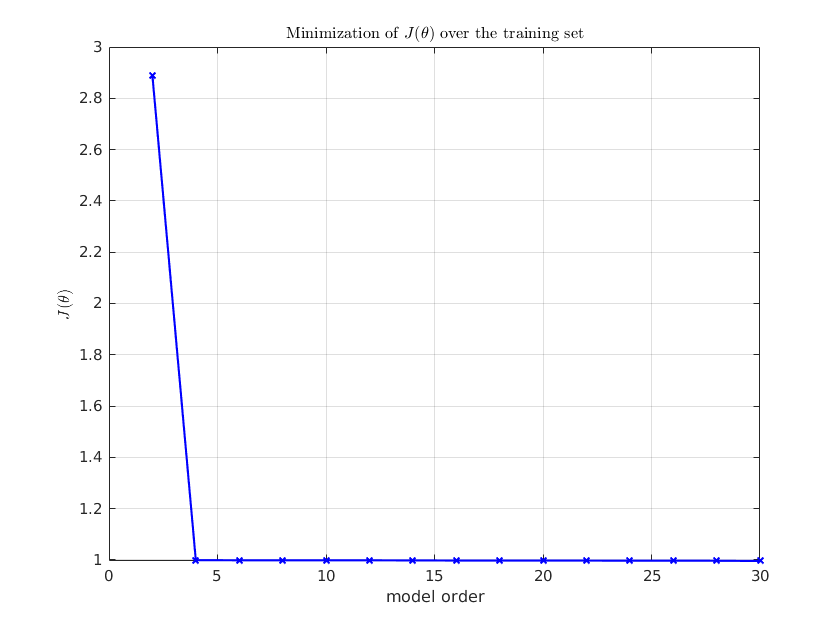

n = 1:15;
J_theta = zeros(length(n),1);
for i=1:length(n)
    theta_hat = LS_ARX(trainingset.u,trainingset.y,i);
    H = myhank(trainingset.u,trainingset.y,i);
    J_theta(i) = cost_fun(trainingset.y,theta_hat,H);
end
[min_J_theta, min_n] = min(J_theta);

figure()
plot(2*n,J_theta,"b-x","LineWidth",1.5)
title("Minimization of $J(\theta)$ over the training set","Interpreter","latex")
xlabel("model order")
ylabel("$J(\theta)$","Interpreter","latex")
grid on

From the plot can be appreciated that the value of the cost function keeps decreasing as the model order increases. In fact, the associated minimum value of $J(\theta)$ gives the following model order:

fprintf("min(J_theta) = %3f and model order = %3f", min_J_theta, min_n*2)

min(J_theta) = 0.995776 and model order = 30.000000

Then, we can say for sure that this method is not reliable to estimate the model order. What about the same approach applied to the validation set? This means, I compute the estimate $\hat{\theta}$ on the training set, and then I evaluate the minimization of the cost function $J(\hat{\theta})$ over the validation set. Let's see the result:

J_theta = zeros(length(n),1);
for j = 1:length(n)
    theta_hat = LS_ARX(trainingset.u,trainingset.y,j); % theta is always computed on the training set
    H = myhank(validationset.u,validationset.y,j); % now computed on the validation set
    J_theta(j) = cost_fun(validationset.y,theta_hat,H); % computed on the validation set
end
[min_J_theta, min_n] = min(J_theta);

Let's plot how the cost function behaves in this case:

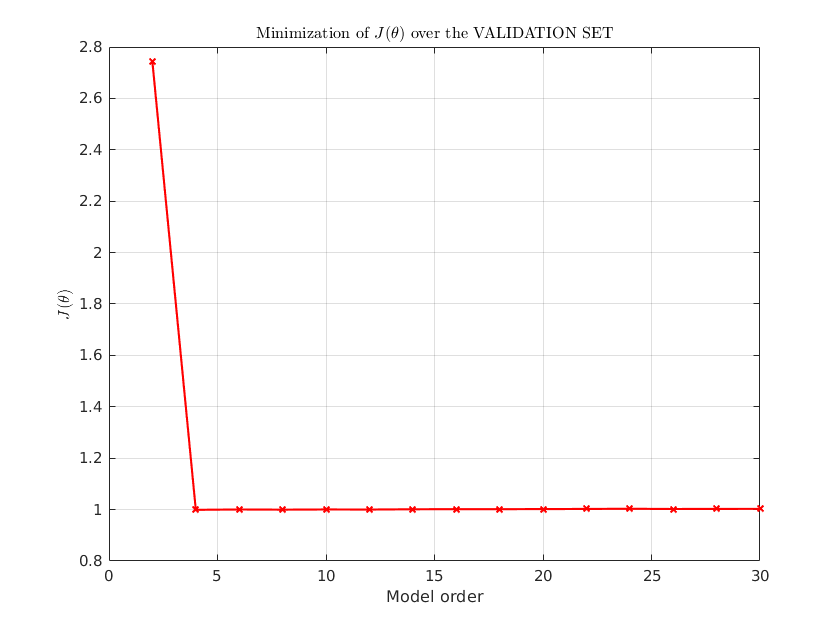

figure()
plot(2*n,J_theta,"r-x","LineWidth",1.5)
title("Minimization of $J(\theta)$ over the VALIDATION SET","Interpreter","latex")
grid on
xlabel("Model order")
ylabel("$J(\theta)$","Interpreter","latex")

From the plot it is not appreciable which is the minimum vale of the cost function, let's print the one calculated before:

fprintf("the minimum value of J is: %3f and the order is: %3f",min_J_theta,2*min_n)

the minimum value of J is: 0.999086 and the order is: 4.000000

From the minimization over the validation set the order estimated is lower that the one obtained before. This method is considered reliable, but there are different methods that can be exploited to verify if this is the real model order or not. In some cases, because of the few samples, it is preferrable to use methods able to validate the model order directly on the training set, and I will use few of them to make my final decision.

#### Final Prediction Error Criterion - FPE

This is a criterion used to estimate the model order based only on the training set. To use this method we have to use the FPE function as:

$FPE=\frac{N+p}{N-p}J(\hat{\theta}_N) \simeq J(\hat{\theta}_N) + \frac{2p}{N}J(\hat{\theta}_N)$ if $N\to\infty$

For $N\to\infty$ the FPE resembles the criteria with complexity terms which in some ways penalize the decrease of the cost function $J(\hat{\theta})$ with increasing orders.

I want to try both the functions, with or without the assumption of $N\to\infty$. 

In order to that, I have defined two different functions: "FPE_nor.m" with the formula without assumption, and "FPE_ass.m" with the assumption. Let's try the two function in a for-loop for different values of $n$:

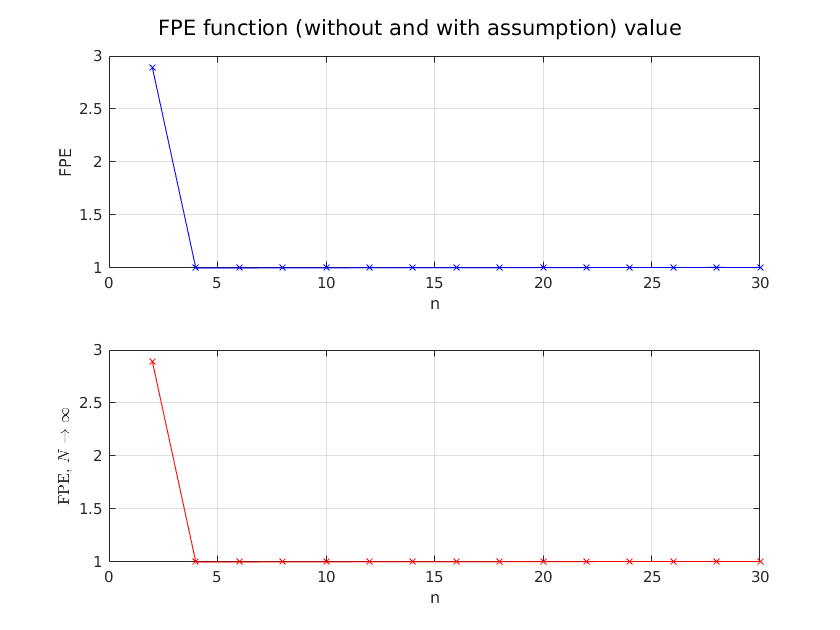

n = 1:15;
FPE_1 = zeros(length(n),1); % initialization for the FPE without assumption
FPE_2 = zeros(length(n),1); % initialization for the FPE with assumption

for i=1:length(n)
    theta_order = LS_ARX(trainingset.u,trainingset.y,i);
    FPE_1(i) = FPE_nor(trainingset.u,trainingset.y,theta_order);
    FPE_2(i) = FPE_ass(trainingset.u,trainingset.y,theta_order);
end

[minFPE_nor, min_n_FPE_nor] = min(FPE_1);
[minFPE_ass, min_n_FPE_ass] = min(FPE_2);

figure()
sgtitle("FPE function (without and with assumption) value")
subplot(2,1,1)
plot(2*n,FPE_1,"b-x")
ylabel("FPE")
xlabel("n")
grid on
subplot(2,1,2)
plot(2*n,FPE_2,'r-x')
xlabel("n")
ylabel("FPE, $N\to\infty$","Interpreter","latex")
grid on

The minimum order estimated by the two FPE are:

fprintf("The FPE without the assumption estimate a model order of: %3f",2*min_n_FPE_nor)

The FPE without the assumption estimate a model order of: 4.000000

fprintf("The FPE with the assumption estimate a model order of: %3f",2*min_n_FPE_ass)

The FPE with the assumption estimate a model order of: 4.000000

The two FPE gives back the same model order. To claim with a certain confidence level that is the true model order, I am going to use other 2 methods based on the criteria with complexity terms to confirm this result. 

#### Akaike Information Criterion - AIC

The akaike Information Criterion is based over the following function:


$$AIC = N\log{J(\hat\theta_N)} + 2p$$


AIC and FPE are asymptoticall equivalent. However, both the method are considered not consistent, in the sense that the convergence of the two criteria to the true order is not guaranteed even if the samples number is very large. 

The AIC function is implemented in the function "AIC.m". Let's apply it:

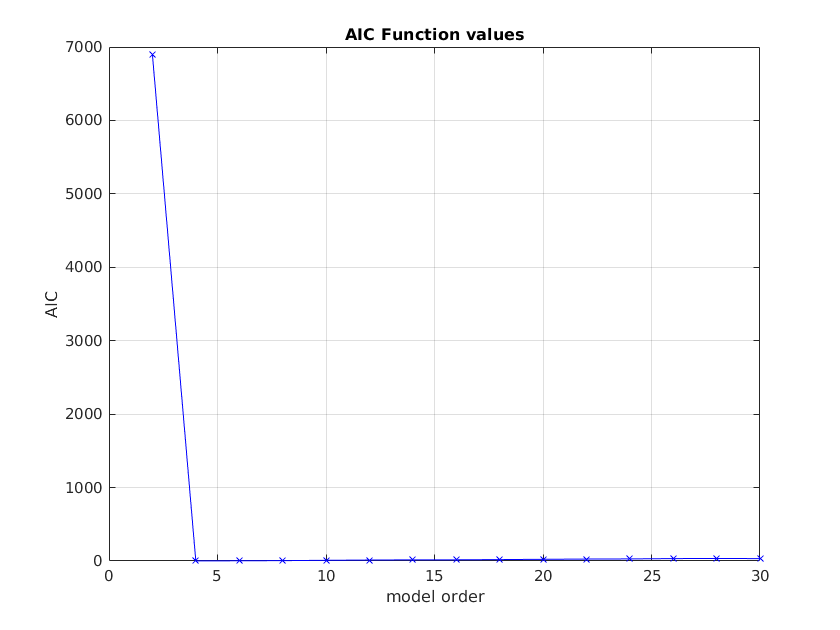

n = 1:15;
AIC_try = zeros(length(n),1); % initialization of the value of AIC function
for i=1:length(n)
    theta_try = LS_ARX(trainingset.u,trainingset.y,i);
    AIC_try(i) = AIC(trainingset.u,trainingset.y,theta_try);
end
[min_AIC, min_n_AIC] = min(AIC_try);
figure()
plot(2*n,AIC_try,'b-x')
ylabel("AIC")
xlabel("model order")
grid on
title("AIC Function values")

fprintf("The model complexity estimated by AIC is: %3f",2*min_n_AIC)

The model complexity estimated by AIC is: 4.000000

Even the AIC gives the same model complexity, to confirm that the model complexity is $p=2n=4$, I will try the last criterion.

#### Minimum Description Length Criterion - MDL

The MDL criterion leads to model of lower complexity (generally) with respect to AIC and FPE, and it is the only one that converges to the true order of the model (if that exists). The MDL is based on the function:


$$MDL = N\log{J(\hat\theta_{N}) + 2p\log{N}$$


Also in this case, the function that computes this criterion is "MDL.m". Let's apply it:

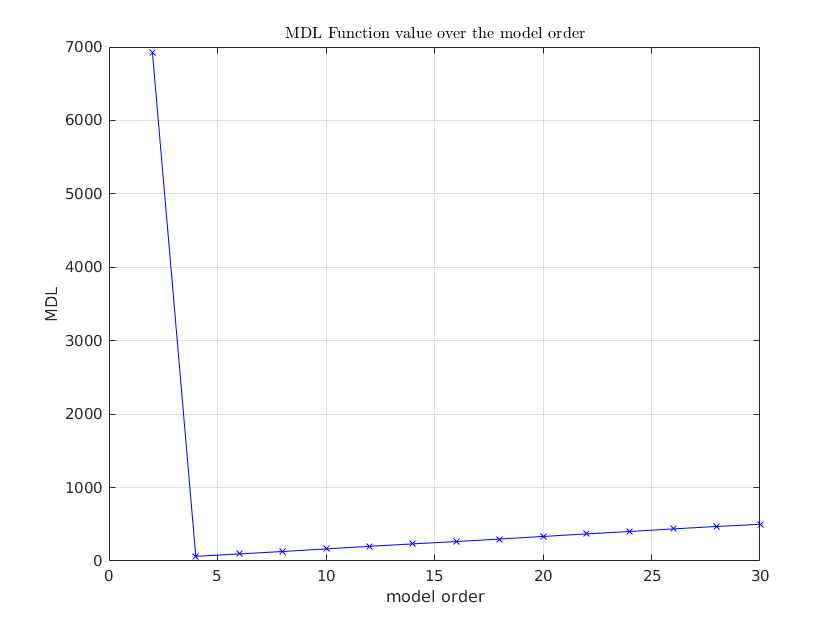

n = 1:15;
MDL_try = zeros(length(n),1); % initialization of the value of MDL function
for i=1:length(n)
    theta_try = LS_ARX(trainingset.u,trainingset.y,i);
    MDL_try(i) = MDL(trainingset.u,trainingset.y,theta_try);
end
[min_MDL, min_n_MDL] = min(MDL_try);

figure()
plot(2*n,MDL_try,'b-x')
ylabel("MDL")
xlabel("model order")
title("MDL Function value over the model order","Interpreter","latex")
grid on

From the plot in this case is clear which is the order of our model. As said, the Minimum Description Length is the one that ensure the convergence to the true model. In fact we have that:

fprintf("The estimated order by the MDL is: %3f", 2*min_n_MDL)

The estimated order by the MDL is: 4.000000

With a certain level of confidence, we can conclude that the order of our model is 4! ( $p=2n=4$)

### Model Estimation - RWLS I

Now we know that the order of our model is $p=4$ and we can apply the estimation algorithms explained before to compute the estimate of the parameters vector $\hat{\theta}$.

In order to do that, I have defined two different functions "RWLS_I.m" and "RWLS_III.m" based on the algorithms seen at the beginning of this document. 

I decided to try both the algorithm to see how they behave. 

We have no clue about the initial conditions of the model, so we will initialize the algorithm from $\hat{\theta}_0 = [0\ \dots\ 0]^T$ which is the worst possible case.

p = 4;
theta_0 = zeros(p,1);
lambda = 0.999;

[theta_hat_I,plot_res] = RWLS_I(trainingset.u,trainingset.y,theta_0,lambda);
disp(theta_hat_I)

    1.0238
    0.2957
    1.2942
    1.0749



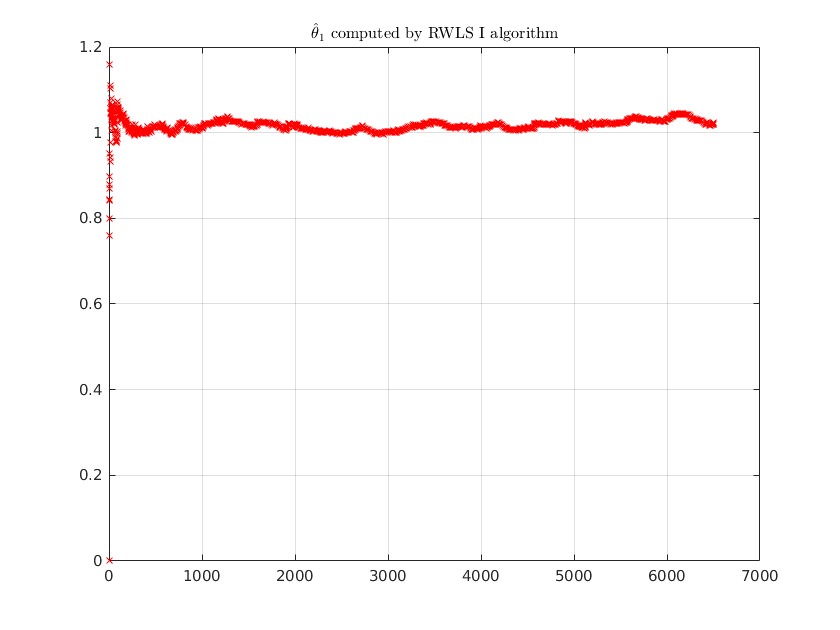

figure()
plot(plot_res(1,:),'rx')
title("$\hat\theta_1$ computed by RWLS I algorithm","Interpreter","latex")
grid on

The plot above represents the value of $\hat{\theta}_1$ over the steps of the algorithm. We can appreciate that as $\lambda \to 1$ the oscillations over time decreasing. I will show that by evaluate the algorithm for different $\lambda$ and then plot the results together:

lambda_1 = 0.95;
lambda_2 = 0.97;
lambda_3 = 0.99;
lambda_4 = 1;

NB $\lambda=1$ results in a non-weighted algorithm

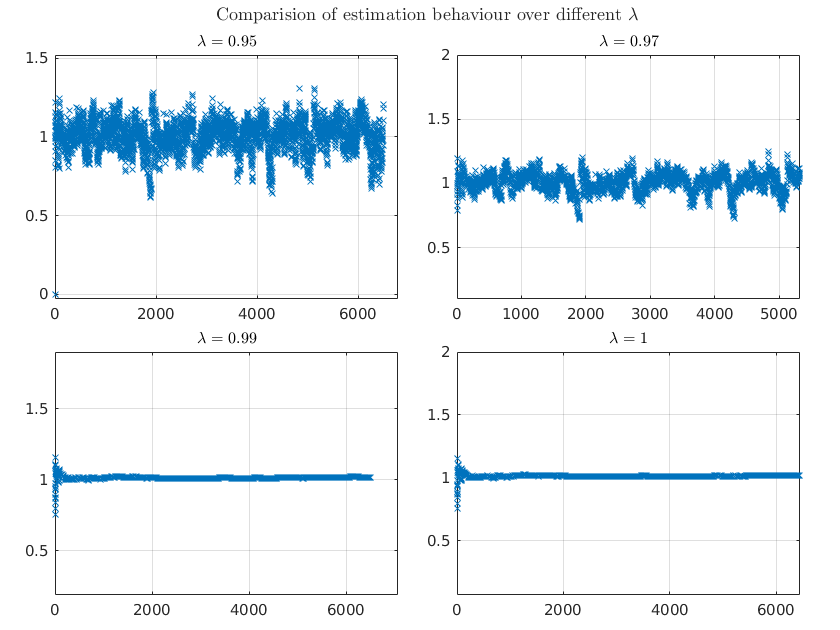

[theta_hat_1, plot_1] = RWLS_I(trainingset.u,trainingset.y,theta_0,lambda_1);
[theta_hat_2, plot_2] = RWLS_I(trainingset.u,trainingset.y,theta_0,lambda_2);
[theta_hat_3, plot_3] = RWLS_I(trainingset.u,trainingset.y,theta_0,lambda_4);
[theta_hat_4, plot_4] = RWLS_I(trainingset.u,trainingset.y,theta_0,lambda_4);

figure()
t = tiledlayout(2,2);

nexttile
plot(plot_1(1,:),'x')
title("$\lambda = 0.95$","Interpreter","latex")
grid on
% axes 1
xlim([0 6789])
ylim([-0.03 1.52])

nexttile
plot(plot_2(1,:),'x')
title("$\lambda = 0.97$","Interpreter","latex")
grid on
% axes 2
xlim([0 5320])
ylim([0.10 2.00])

nexttile
plot(plot_3(1,:),'x')
title("$\lambda = 0.99$","Interpreter","latex")
grid on
% axes 3
xlim([0 7064])
ylim([0.19 1.90])

nexttile
plot(plot_4(1,:),'x')
title("$\lambda = 1$","Interpreter","latex")
grid on
% axes 4
xlim([0 6447])
ylim([0.07 2.00])

t.Padding = 'compact';
t.TileSpacing = 'compact';
title(t,"Comparision of estimation behaviour over different $\lambda$","interpreter","latex")

Now it is appreciable that as the value of $\lambda$ increases, the oscillations in the estimation decreases. For sake of simplicity, I have always plotted $\hat{\theta}_1$.

I will keep as reference the $\hat{\theta}$ estimated by $\lambda = 0.999$, which is:

disp(theta_hat_I)

    1.0238
    0.2957
    1.2942
    1.0749



### Model Estimation - RWLS III

Now I want to try the estimate based on a different RWLS algorithm, the one with the matrix inversion lemma. In order to do that, I have written the algorithm in the function "RWLS_III.m".

In this case we have also to initialize the matrix $P(0)$, but as for $\hat{\theta}_0$ we have no clue about its shape. Then, an approach is to set it as:


$$P(0) = \alpha I_p$$
 

where:

- $\alpha$ is a scalar

- $I_p$ is the identity matrix of dimension $p$

The value of the parameters $\alpha$ is inversely proportional to the confidence we have about the initialization of $\hat{\theta}$. $\alpha$ small $\to$good confidence; $\alpha$ big $\to$bad confidence. 

Now let's apply the algorithm and see the results:

alpha = 10000;
lambda = 0.999;
p = 4;
theta_0 = zeros(p,1);
[theta_hat_III, plot_res_III] = RWLS_III(trainingset.u,trainingset.y,theta_0,alpha,lambda);
disp(theta_hat_III)

    1.0238
    0.2957
    1.2942
    1.0749



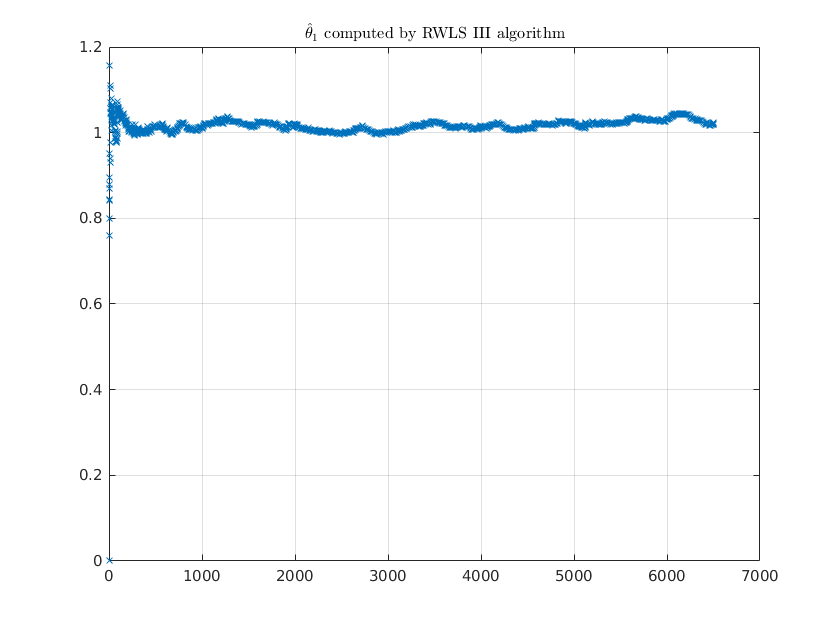

figure()
plot(plot_res_III(1,:),'x')
grid on
title("$\hat\theta_1$ computed by RWLS III algorithm","Interpreter","latex")

The estimation is complete and both algorithm gives the same result, without loss of generality I can choose $\hat{\theta}_{RWLS_I}$ or $\hat{\theta}_{RWLS_{III}$ . 

## **4) Model Validation**

Now, once we have chosen the model order ($p=4$) and estimated the parameters vector $\hat{\theta}$, we have to validate the model and verify its capability to describe the real process that generates the initial dataset. 

In order to that, there are two assumptions that we have to verify:

- $\epsilon(t,\hat\theta_N)$ is a zero-mean white process;

- $\epsilon(t,\hat\theta_N)$ is uncorrelated with the input $u(t)$ (we have also to assume a large dataset $N \to \infty$)

Where $\epsilon(t,\hat{\theta}_N)$ represents the residuals obtained given the estimated vector of parameters $\hat{\theta}_N$. To verify them, I will apply two different tests: **whiteness test **and **cross-correlation test**.

#### Whiteness Test

We have a sequence of residuals $\epsilon(1,\hat\theta_N),\dots,\epsilon(N,\hat\theta_N)$ and we perform a STATISTICAL HYPOTHESIS TEST:


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right) \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


There are two version of the test, the $\chi^2(m)$ based and the Gaussian test based.

 The $\chi^2$ test is defined as follows


$$\left\lbrace \begin{array}{ll}
H_0: x \le \chi^2_{\alpha}(m) \\
H_1: x \gt \chi^2_{\alpha}(m)
\end{array}$$


where the test quantity $x$ is


$$x = N\frac{\hat{r}^T_{\epsilon}\hat{r}_{\epsilon}}{\hat{r}^2_{\epsilon}(0)}$$


The $\chi^2$ test is implemented in the function "wtest_chi.m".  

The Gaussian test is defined as follows

$\sqrt{N}\hat\gamma(\tau) \sim \mathcal{N}(0,1)$ as $N \to \infty$ and $\tau = 1,\dots,m$

where


$$\hat\gamma(\tau) = \frac{\hat{r}_{\epsilon}(\tau)}{\hat{r}_{\epsilon}(0)}$$
       
$$\tau = 1,\dots,m$$


is the normalized autocorrelation function. 

The Gaussian Test is defined as

$\left\lbrace \begin{array}{ll}
H_0^{\tau}: \vert\frac{\hat\gamma(\tau)}{\sqrt{N}}\vert \leq z \\
H_1^{\tau} : \vert\frac{\hat\gamma(\tau)}{\sqrt{N}}\vert \gt z
  
\end{array}\right.$     where $\tau = 1, \dots ,m$ 

and $z$ is computed from the Normal Distribution table remembering that $P(x\leq{z}) = 1 - \frac{\alpha}{2}$.

The Whiteness Gaussian test is built in the function "wtest_gauss.m". 

To apply the Whiteness Tests, we should also have computed the vector of residual upon which we will try the test. 

A very effective way of evaluating the adequacy and the flexibility of the identified models consist in testing its predictive capabilities, thus perform whiteness and cross-correlation test by using the validation set. 

Then, it is necessary to compute the residuals of the validation set that are different from the one computed by the RWLS_I (or RWLS_III) algorithm. To do that I have created a new function called "residuals.m".

epsilon_val = residuals(validationset.u,validationset.y,theta_hat_I);

Once the residuals are computed, let's apply the two test to check the **whiteness** of them. First, the $\chi^2$:

significance_level = 0.05;
m = 50;
whitenes_chi_square = wtest_chi(epsilon_val,m,significance_level);
if whitenes_chi_square == 1
    disp("Chi_square Whiteness test Passed !")
else
    disp("Chi_square Whiteness test failed !")
end

Chi_square Whiteness test Passed !


Then, let's see if the result is the same by applying also the Gaussian test:

whiteness_gauss = wtest_gauss(epsilon_val,m,significance_level);
if whiteness_gauss == 1
    disp("Gaussian Whiteness test Passed !")
else
    disp("Gaussian Whiteness test Failed !")
end

Gaussian Whiteness test Failed !


I will also plot the autocorrelation function of $\epsilon(.,\hat{\theta})$ to see its behaviour:

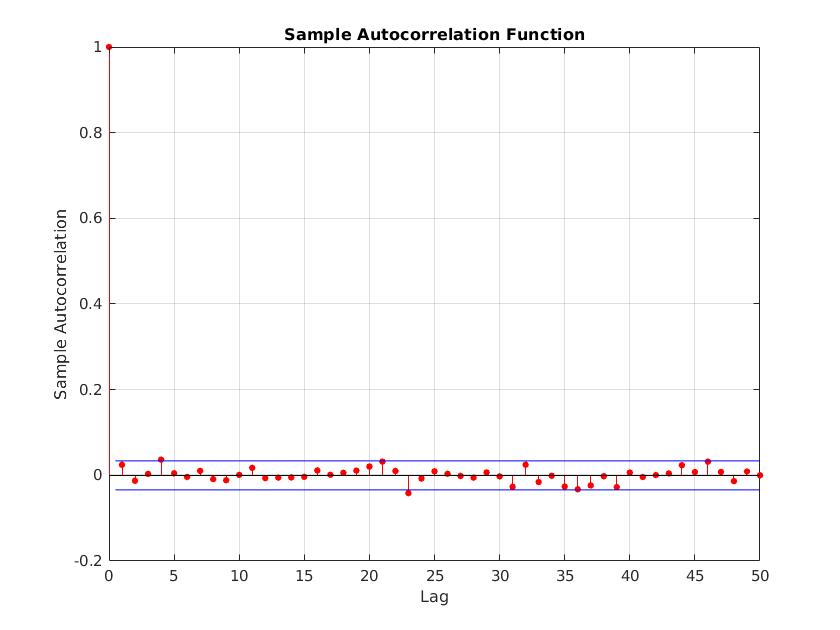

autocorr(epsilon_val,m)

It is not strictly necessary that both $\chi^2$ and Gaussian are passed, at least one of them is sufficient to validate the assumption.

Once this test is concluded, we can move on to the next test.

#### Cross-Correlation test (between $\epsilon(t,\hat{\theta}_N)$ and $u(t)$)

This test is defined as follows


$$\left\lbrace \begin{array}{ll}
H_0 :\epsilon \left(t,\hat{\theta_N } \right)\ and \ u(t)\ \mathbf{uncorrelated} \\
H_1 :\mathrm{not}\;H_0  
\end{array}\right.$$


considering the following vector of sample cross correlation


$$\hat{r}_{\epsilon{u}} = \left[ \begin{array}{ll}
\hat{r}_{\epsilon{u}}(\overline\tau+1) \\
\hat{r}_{\epsilon{u}}(\overline\tau+2) \\
\vdots \\
\hat{r}_{\epsilon{u}}(\overline\tau+m)
\end{array} \right]$$


where $\overline\tau \ge n$. This reason comes from the fact that if we use $\overline\tau$ lower than this value some cross-correlation between input and output will be 0 by construction and they will be useless. In fact, the result will not properly mean "uncorrelated", but it will give back 0 just for the way they are defined falsifing the test. 

Also in this case, it is possible to apply the $\chi^2$ or the gaussian test and I will apply both.

The two test quantities are:

- for the $\chi^2$: $x = N\frac{\hat{r}_{\epsilon u}^T\hat{\Sigma}_u^{-1}\hat{r}_{\epsilon u}}{\hat{r}_{\epsilon}(0)}$

- for the Gaussian: $\hat\gamma(\tau) = \frac{\hat{r}_{\epsilon{u}}(\tau)}{\sqrt{\hat{r}_{\epsilon}(0)\hat{r}_u(0)}}$

where $\hat\Sigma_u$ is the sample autocovariance matrix defined as $\hat\Sigma_u = \frac{1}{N}\sum\varphi_u(t)\varphi^T_u(t)$, and $r_{\epsilon u}$ the autocorrelation function between the residuals and the input.

NB Since $u(t)$ in our case is a white noise, $r_u(0) = Var(u) = \sigma^2_{u}$

The two tests are defined in the functions "cross_corr_chi.m" and "cross_corr_gauss.m".

Let's apply the two test and see the results:

cross_chi = cross_corr_chi(epsilon_val,validationset.u,m,significance_level,p/2);
if cross_chi == 1
    disp("Chi_square Cross-correlation test Passed !")
else
    disp("Chi_square Cross-correlation test failed !")
end

Chi_square Cross-correlation test Passed !


cross_gauss = cross_corr_gauss(epsilon_val,validationset.u,m,significance_level,p/2);
if cross_gauss == 1
    disp("Chi_square Cross-correlation test Passed !")
else
    disp("Chi_square Cross-correlation test failed !")
end

Chi_square Cross-correlation test Passed !


Also in this case it is not necessary that both tests are passed to claim that input and residuals are uncorrelated, we need at least one of them. 

The whiteness and the cross-correlation test are passed, then the model can be validated. To see how good the model estimated is in representing the data, I will plot the the prediction $\hat{y}(t) = \varphi(t)^T\hat{\theta}$ by using the validation set comparing it with $y(t)$. For a good model, $\hat{y}(t)$ should resemble the measured output $y(t)$. Let's see:

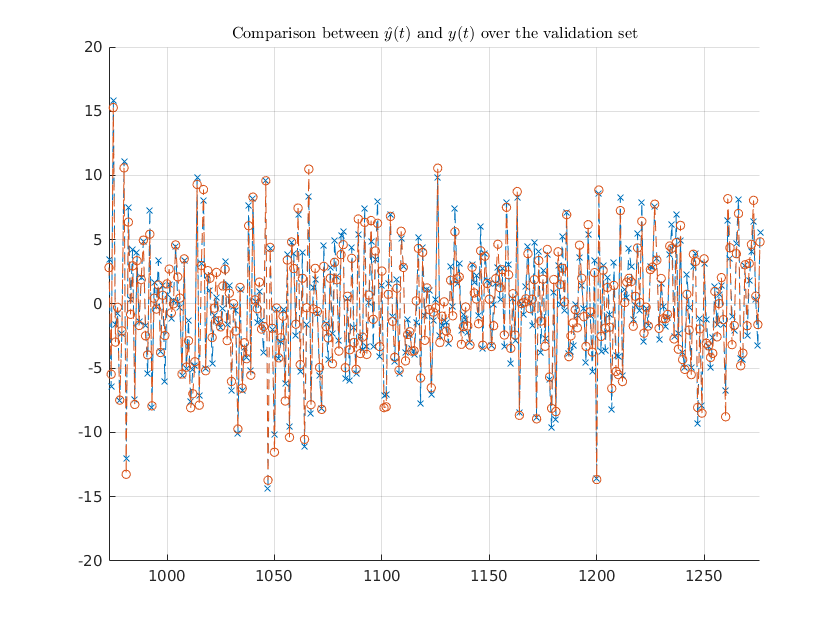

p = 4;
n = p/2;
H = myhank(validationset.u,validationset.y,n);

figure()
hold on
title("Comparison between $\hat{y}(t)$ and $y(t)$ over the validation set","Interpreter","latex")
plot(validationset.y(n+1:end),'--x')
plot(H*theta_hat_I,'--o')
hold off
grid on, zoom on
xlim([973 1276])
ylim([-20.0 20.0])

The model seems to follow quite well the measured output $y(t)$.

Before moving on, I am asked to compute the covariance matrix of the estimate, that for an ARX model results to be:

 
$$cov(\hat{\theta}_N) = \sigma^2_w(H^TH)^{-1}$$


where:

$\sigma_w^2$ is the variance of the white noise $\sim$ $\sigma_{\epsilon}^2$

To compute the covariance matrix, we need an estimate of $\hat{\sigma}^2_w$ that from theory we know is $\hat{\sigma}^2_w = J(\hat{\theta})$, Then:

H = myhank(trainingset.u,trainingset.y,n);
J_theta = cost_fun(trainingset.y,theta_hat_I,H);
cov_theta = J_theta*pinv(H'*H)

cov_theta = 	1.0e+-3 *

    0.0535    0.0152    0.0003    0.0696
    0.0152    0.0115    0.0001    0.0198
    0.0003    0.0001    0.0154    0.0004
    0.0696    0.0198    0.0004    0.1061


The element of the main diagonal are the variances of the estimates ( i.e. $\sigma_{\theta_i}^2$) and their square roots (the standard deviations) give us an idea of how reliable our estimates are. Let's compute them:

dev_params = zeros(length(theta_hat_I),1);
for i=1:length(theta_hat_I)
    dev_params(i) = sqrt(cov_theta(i,i));
end
disp(dev_params)

    0.0073
    0.0034
    0.0039
    0.0103



The standard deviation seems to be very small (unless $\theta_4$ which is slightly higher), then the parameters are not so far from their mean values. We can claim that our estimates are reliable.

The model seems to follow quite well the measured output $y(t)$, so I can conclude that the model is **validated** and the exercise 1 is finished.

# Exercise 2 - Classification Problem 

### 0. Initialization

We first initialize the problem by calling the feature set. 

N = 5000;
Student = 'Alessandro Cecconi';
Matriculation = '0000983867';
FeatureSet = ClassifyThis(N,Student,Matriculation);
Utrain = FeatureSet.Utrain;
Ytrain = FeatureSet.Ytrain;
Utest = FeatureSet.Utest;
Ytest = FeatureSet.Ytest;

### 1) Feature set analysis

n_train = length(Ytrain);
n_test = length(Ytest);
n_u_train = size(Utrain,2);
n_u_test = size(Utest,1);

The first thing to do is to plot the data of the feature set to understand its shape and see if it is necessary to apply some transformation. 

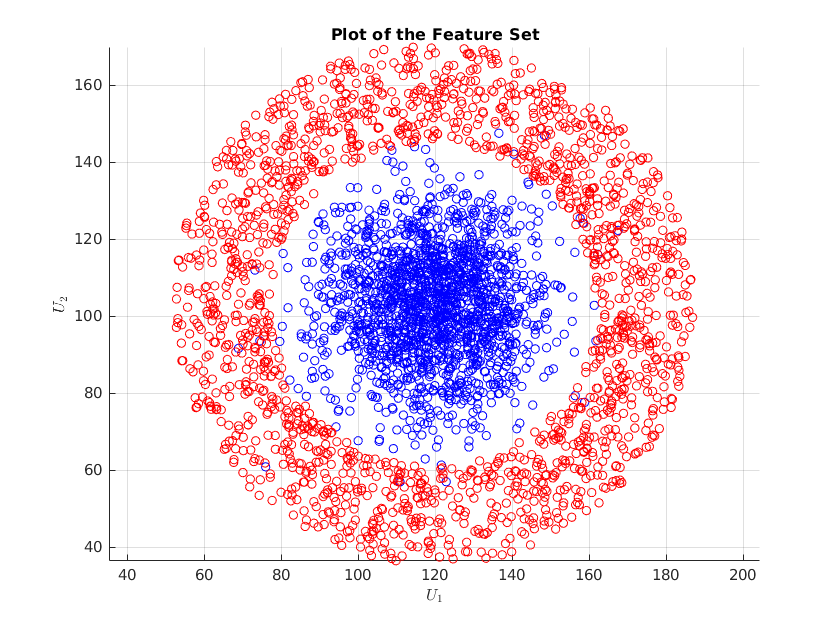

figure()
hold on
grid on
plot(Utrain(Ytrain==0,1),Utrain(Ytrain==0,2),'bo')
plot(Utrain(Ytrain==1,1),Utrain(Ytrain==1,2),'ro')
axis equal
hold off
xlabel("$U_1$","interpreter","latex")
ylabel("$U_2$","interpreter","latex")
title("Plot of the Feature Set")

It is clearly visible from the picture that we are in the case of nonlinear boundaries, so we must perform a nonlinear transformation in order to get back to linear decision boundaries.

We define first an approximate center of the data by using the following formulas:

center_u_1 = (min(Utrain(:,1)) + max(Utrain(:,1)))/2;
center_u_2 = (min(Utrain(:,2)) + max(Utrain(:,2)))/2;

Then, we define the linearized input variables $\overline{u}_1(t)$ and $\overline{u}_2(t)$ as

Utrain_bar_1 = (Utrain(:,1) - center_u_1).^2; %definition of the new dataset given the circunference equation
Utrain_bar_2 = (Utrain(:,2) - center_u_2).^2;
Utrain_bar = [Utrain_bar_1 Utrain_bar_2];

And finally we plot the lnearized feature set as follows:

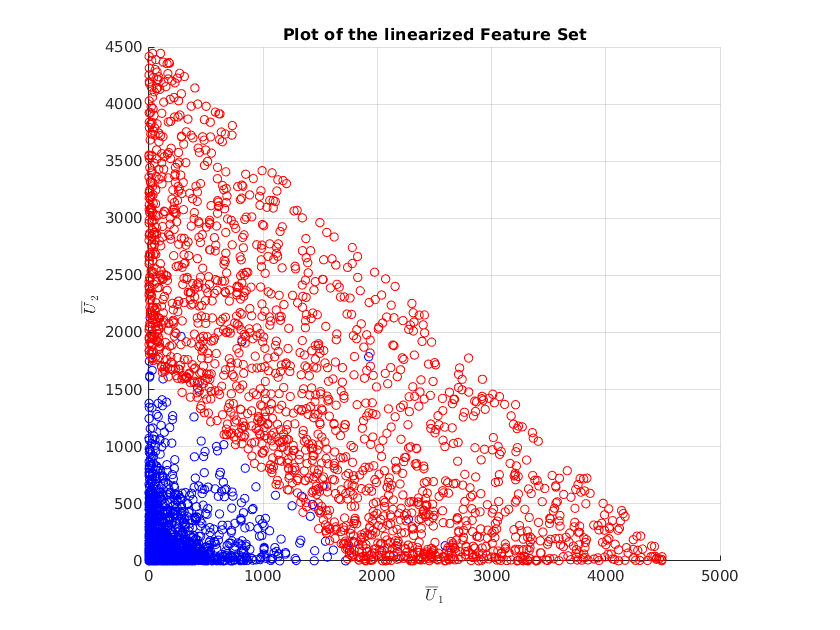

figure()
hold on
grid on
plot(Utrain_bar(Ytrain==0,1),Utrain_bar(Ytrain==0,2),'bo')
plot(Utrain_bar(Ytrain==1,1),Utrain_bar(Ytrain==1,2),'ro')
axis equal
hold off
xlabel("$\overline{U}_1$","interpreter","latex")
ylabel("$\overline{U}_2$","interpreter","latex")
title("Plot of the linearized Feature Set")
xlim([-1 5000])
ylim([-1 4500])

In this case the model complexity is not increased, the number of inputs is the same as in the case of the nonlinear decision boundaries:

if size(Utrain) == size(Utrain_bar)
    fprintf("Same complexity \n")
else
    fprintf("The model complexity increased \n")
end

Same complexity 


From the graphs it is appreciable that we are in a two-class problem with nonlinear boundaries that can be solved by means of a nonlinear transformation, we'll see it in the next section.

The problem must be solved by using the logistic regression and by applying the Newton-Raphson algorithm, then we are in the case of Probabilistic Models. Let's recall the following quantities that we'll be used to evaluate the classifier performances:

- Error Rate $E_r$: 


$$E_r = \frac{1}{N}\sum_{t=1}^{N}I(y(t),\hat{y}(t))$$


- Indicator Variable $I(y(t),\hat{y}(t))$


$$I(y(t),\hat{y}(t)) = \begin{cases} 1 & if\ y(t) \neq \hat{y}(t) \\ 0 & if\ y(t) = \hat{y}(t) \end{cases}$$


The error rate $E_r$ is the fraction of misclassifed observations and $\hat{y}(t)$ is the prediction of $y(t)$ given by the classifier.

To solve Probabilistic Models, we have studied the so-called **Bayes Classifier**, which assign to each input the most-likely class by solving the following problem:


$$C_i = \underset{i}{\arg\max}P(C_i | u(t)) = P(y(t) = y^i | u(t))$$


Since we are in a two-class problem, we will assign the input to class $C_1$ if $P(C_1|u(t)) > 0.5$ or to class $C_2$ if not. The problem in a real data setting is that we do not really know the conditional probabilities between $\mathcal{U}$ and $\mathcal{Y}$, we need to define a method to estimate them to solve the problem, and we make use of the **Logistic Regression** as I'll describe later on. 

Let's define now the Classification algorithm.

### 2) Classification Algorithm Definition

The first plot clearly resembles a circumference, so we define the decision boundaries as


$$\beta_0 + \beta_1u_1^2(t) + \beta_2u_2^2(t) = 0$$


By applying the nonlinear transformation that we know from the theory


$$u(t)\in\mathcal{U} \to \overline{u}(t)\in\overline{\mathcal{U}}$$


We will obtain:

$\beta_0 + \beta_1\overline{u}_1(t)+\beta_2\overline{u}_2(t) = 0$ where $\overline{u}_i = u^2_i(t)$

$\overline{\varphi}(t)^T = [1\  \overline{u}_1(t)\  \overline{u}_2(t)]$ and $\theta = [\beta_0\ \beta_1\ \beta_2]^T$

That are used to write the function in compact form as:


$$z(t) = \overline{\varphi}(t)^T\theta$$


phibar_t = [ones(n_train,1) Utrain_bar];

Our goal now is to estimate the parameters of $\theta$ to find the decision boundaries. In order to do that, we will use the **Logistic regression. **The regression is based on the so-called **sigmoid function **$f(z(t))$ to construct the conditional probabilities needed to classify to which class the inputs belong to. This function has to be a specific set of properties which makes it very similar to a cumulative distribution function. In fact $f(z(t))$ must be such that:


$$f(z(t))\in(0,1)$$


$f(z(t)) > 0.5 \ if\ z(t) > 0$ and viceversa

$f(z(t)) \to 1$ if $z(t) \to \infty$ and $f(z(t)) \to 0$ if $z(t) \to -\infty$


$$f(z(0)) = 0.5$$


. The shape of the sigmoid function is defined as:


$$f(z(t)) = \frac{e^{z(t)}}{1+e^{z(t)}}$$


This function is implemented in the matlab function "sig_fun.m".

Also in this case we have to deal with an estimation problem, but we have to find first the shape of the discriminant function $z(t)$ before being able to compute the following conditional probabilities:


$$P(C_1|u(t)) = f(z(t))$$



$$P(C_2|u(t)) = 1-f(z(t))$$


where $z(t)$ can be defined as


$$z(t) = log\frac{P(C_1|u(t))}{P(C_2|u(t))}=log\frac{f(z(t))}{1-f(z(t))}$$


Our goal is to maximize the conditional probability of the observation of the training set. To solve this problem, we make use of the **Maximum Likelihood Estimation **to find a vector of parameters $\theta$ which maximizes this probability. Using the log-likelihood function the problem becomes a minimization problem, In fact:


$$J(\theta) = -log(P(Y|\theta)) = - \sum_{t=1}^N [y(t)log(f(z(t))) + (1-y(t))log(1-f(z(t)))]$$


And the problem can be rewritten as:


$$\min_{\theta} J(\theta)$$


The following cost function is defined in the function "log_lik_cost.m".

In order to minimize this function and get the parameters vector, we were asked to use the **Newton-Raphson Algorithm **which is an iterative algorithm that refine the solution at each iteration. We are forced to use an iterative algorithm since the solution in closed-form cannot be computed. The algorithm step is: 

$\hat{\theta}^{k+1} = \hat{\theta}^k - \alpha_kJ^{''}(\hat{\theta}^k)^{-1}J^{'}(\hat{\theta}^k)^T$ where $\alpha_k$ is the stepsize and


$$J^{'}(\theta) = \Phi^T(F(\theta) - Y)$$



$$J^{''}(\theta) = \Phi^TW(\theta)\Phi$$



$$\Phi = \left[\begin{array}{ll}
1 & u_1(1) & \dots & u_r(1) \\
\vdots & u_1(2)  & \dots & u_r(2) \\
\vdots & \vdots & \ddots & \vdots \\
1 & u_1(N) & \dots & u_r(N)


\end{array} \right]$$



$$Y = [y(1)\ \dots \ y(N)]^T$$



$$F(\theta) = [f(z(1))\ \dots \ f(z(N))]^T$$



$$W(\theta) = \left[\begin{array}{ll}
f(z(1))(1-f(z(1)) & \ \ \ \ \ \ \ \ 0 & \dots & \ \ \ \ \ \ \ \ 0 \\
\ \ \ \ \ \ \ \ 0 & f(z(2))(1-f(z(2)) & \dots & \ \ \ \ \ \ \ \ 0 \\
\ \ \ \ \ \ \ \ 0 & \ \ \ \ \ \  \ \ \dots & \dots & f(z(N))(1-f(z(N)) \\
\end{array}\right]$$


The gradient and the Hessian of the cost function are defined in the functions "gradient.m" and "hessian.m". 

The algorithm should be initialized and our condition is that we start from the simplest initialization possible, a simple vector of zeros $\hat{\theta}^0 = [0\ 0\ 0]^T$.Since it is an iterative algorithm, we also need a condition to stop it, our stop criterion is:

$|J(\hat{\theta}^{k+1}) - J(\hat{\theta}^k)| \leq \epsilon$ if it holds I'll stop the algorithm

 Let's summarize the algorithm steps:

0. Initialize $\epsilon$ and $\hat{\theta}^0$

At a generic step k:

- Save the $\hat{\theta}^k$ computed at previous step;

- Compute the associated cost function $J(\hat{\theta}^k)$;

- Compute Gradient and Hessian: $J^{'}(\hat{\theta}^k)$ and $J^{''}(\hat{\theta}^k)$;

- Compute $\hat{\theta}^{k+1}$

- Check the stop criterion: if not satisfied goes on at step k+1.

Then let's apply the algorithm and see how it works (and if works). First, we define the vector $\hat{\theta}^0$:

[~,n]= size(phibar_t); %model complexity 
theta_0 = zeros(n,1); % initialization of theta_0

We define also the threshold for the stop criterion $\epsilon$ and the stepsize $\alpha_k$

alpha_k = 0.1;
epsilon_val = 10e-4;

The Algorithm summarized above is entirely written in the function "Newton-Raphson.m" which I am going to call to solve the classification problem:

[theta_star, plot_J] = Newton_Raphson(Ytrain,phibar_t,theta_0,alpha_k,epsilon_val);
disp(" Logistic regression result by Newton-Raphson Algorithm: ")

 Logistic regression result by Newton-Raphson Algorithm: 


disp(theta_star)

  -12.6193
    0.0076
    0.0078



Now, let's see the plot of the cost function with respect to the number of iterations:

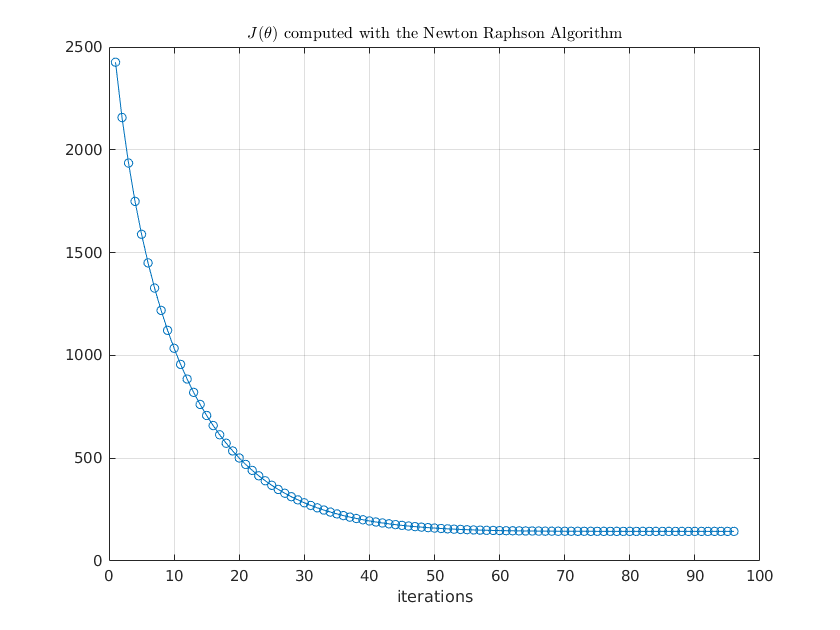

figure()
plot(plot_J,"-o")
title("$J(\theta)$ computed with the Newton Raphson Algorithm","interpreter","latex")
xlabel("iterations")
grid on

Now, let's see how our linearized dataset by plotting the decision boundary based on the value $\theta^*$ we have obtained from the algorithm:

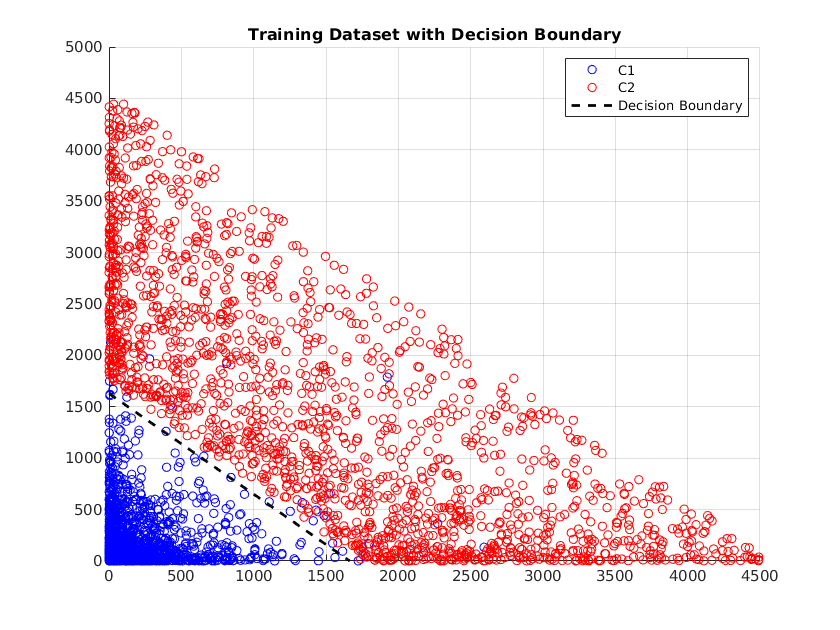

figure();
hold on 
grid on
plot(Utrain_bar(Ytrain==0,1),Utrain_bar(Ytrain==0,2),'bo');
plot(Utrain_bar(Ytrain==1,1),Utrain_bar(Ytrain==1,2),'ro');
Xlim=xlim();
xspace = Xlim(1):0.1:Xlim(end);
BoundaryLine = (theta_star(1) + xspace.*theta_star(2))./(-theta_star(3));
plot(xspace,BoundaryLine,'--k','LineWidth',2);
xlim(Xlim);
hold off
title('Training Dataset with Decision Boundary');
legend({'C1','C2','Decision Boundary'});
ylim([-1 5000]);
xlim([-1, 4500]);

### 3) Classificator Test

Now, how do we classify a new input? From the theory we know that:

If $f(\hat{z}(t)) > 0.5$ then we assign $u(t)$ to $C_1$ (i.e. $\hat{y}(t) = 1$), otherwise we assign the input to class $C_2$ (i.e. $\hat{y}(t) = 0$). This classification is done by means of the function "classifier.m" that I have created to perform this task. By recalling also the Indicator Variable:


$$I(y(t),\hat{y}(t)) = \begin{cases} 1 & if\ y(t) \neq \hat{y}(t) \\ 0 & if\ y(t) = \hat{y}(t) \end{cases}$$


We perform the classification as follows:

Y_hat = classifier(phibar_t,theta_star);
I_train = 0;
for i=1:length(Y_hat)
    if Y_hat(i) ~= Ytrain(i)
        I_train = I_train + 1;
    end
end

And taking into account the number of misclassified inputs we can compute the error rate $E_r$ as:

Error_rate_train = I_train/n_train;
fprintf("The error rate (in percentage) for the classifier results to be: %3f",Error_rate_train*100)

The error rate (in percentage) for the classifier results to be: 0.828571

Since the error rate results to be very small, I can claim that the classifier can be accepted. 

To conclude the task, let's try the classification on the **test test **to see how the classifier works fine:

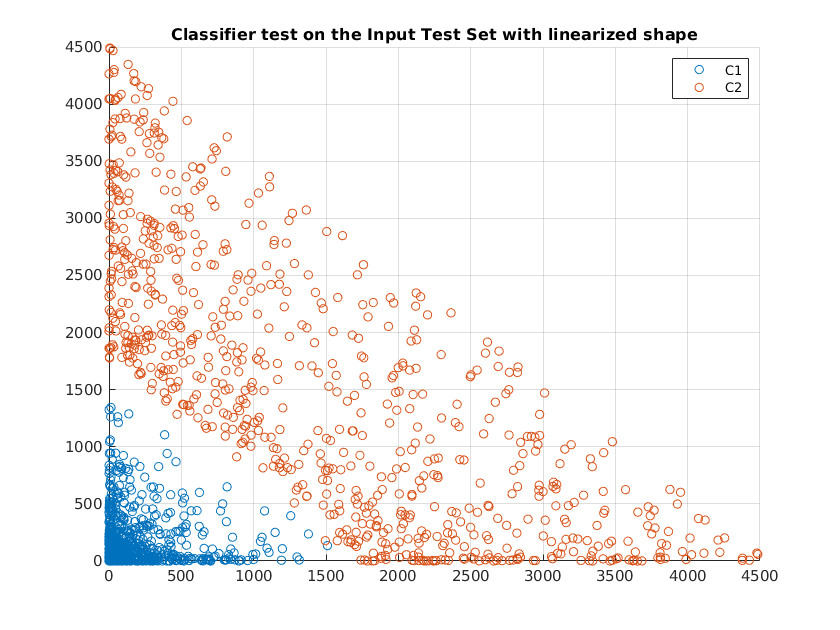

Utrain_test_1 = (Utest(:,1) - center_u_1).^2;
Utrain_test_2 = (Utest(:,2) - center_u_2).^2;
Utest_bar = [Utrain_test_1 Utrain_test_2];

phi_test_t = [ones(n_u_test,1) Utest_bar];
Y_hat_test = classifier(phi_test_t,theta_star);

figure()
hold on
plot(Utest_bar(Y_hat_test==0,1),Utest_bar(Y_hat_test==0,2),'o')
plot(Utest_bar(Y_hat_test==1,1),Utest_bar(Y_hat_test==1,2),'o')
legend({'C1','C2'})
hold off
grid on
title("Classifier test on the Input Test Set with linearized shape")

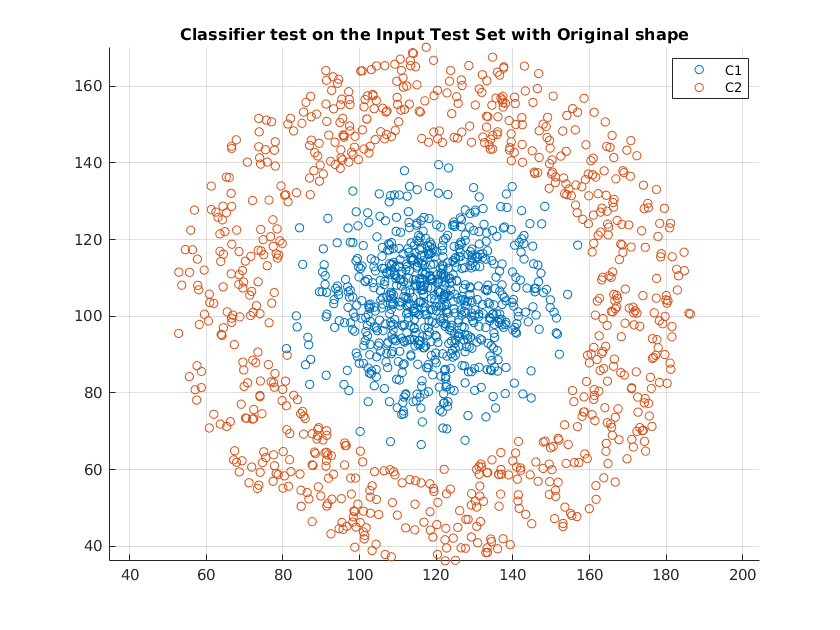


figure()
hold on
plot(Utest(Y_hat_test==0,1),Utest(Y_hat_test==0,2),'o')
plot(Utest(Y_hat_test==1,1),Utest(Y_hat_test==1,2),'o')
legend({'C1','C2'})
grid on
axis equal
hold off
title("Classifier test on the Input Test Set with Original shape")

Before conclude the exercise, let's see the Error rate on the test set:

I_test = 0;
for i=1:length(Y_hat_test)
    if Y_hat_test(i) ~= Ytest(i)
        I_test = I_test + 1;
    end
end
Error_rate_test = I_test/n_test

Error_rate_test = 0.0067

fprintf("The Error rate evaluated on the Train set results to be (in percentage): %3f", Error_rate_test*100)

The Error rate evaluated on the Train set results to be (in percentage): 0.666667

The classifier seems to be pretty good, so the exercise is concluded.